clear all;
close all;
clc;

%load data written by NY

Animal = 'tph316'; %'tph199'; %'s19';
Date = '20240320'; %'20230602';'20230827'
totalTrial = 150;
Key = 'roving'; %'roving25s' 'light90';
target_fps = 10;
F_over_dV = -365; %160; -192.4; %23/4~ -372; % 23/8~ -247; % 24/2~ -365; % 24/7~ -498
force_thres = 100000; %20 %0.1 % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022'; % Linux
data_folder = ['/media/naohiro/Volume/Nao_behavior/202403'  filesep Date '_' Animal '_' Key]; % from 24/6
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation/202308'  filesep Date '_' Animal '_' Key]; % Linux % /202308
% resistance_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'behavior.csv']); %,'NumHeaderLines',1);
resistance_table = readtable([data_folder filesep 'resistance.csv']);%,'NumHeaderLines',1);

behavior_table = readtable([data_folder filesep 'behavior.csv']); %,'NumHeaderLines',1);

% define each task related variable
resistance = resistance_table.('resistance'); % state1: 8 (light) or 20 (heavy)
trial = behavior_table.('trial_'); % 1-150, 0: out of trial 
position = behavior_table.('position'); % state2: 630-647
force = behavior_table.('dVoltage'); % action: 0 ~ 0.8?
reward = behavior_table.('pumpReward'); % reward: 0 or 1 in end of trial
time = behavior_table.('time'); % time points (ms)

force = force*F_over_dV;

% devide behavior sequence by trial and combine to resistance
behavior_sequence = cell(1,totalTrial); %zeros(totalTrial);
sucess_rate = 0;
for i_trial = 1:totalTrial
%     behavior_temp_list = [];
    trial_idx = find(trial == i_trial);
    position_temp = position(trial_idx);
    force_temp = force(trial_idx);
    reward_temp = zeros(length(position_temp),1); %reward(trial_idx);
    if reward(max(trial_idx)+1) == 1
        reward_temp(length(position_temp)) = 1;
        sucess_rate = sucess_rate + 1;
    end
    time_temp = time(trial_idx);
    i_trial_list = transpose(repelem(i_trial,length(position_temp)));
    resistance_list = transpose(repelem(resistance(i_trial),length(position_temp)));
    behavior_sequence{i_trial} = [i_trial_list resistance_list position_temp force_temp reward_temp time_temp];
end

% remove trials more than threshold force is imposed before start of trial
behavior_sequence_processed = cell(1);
processed_idx = 0;
for i_trial = 1:totalTrial
    if behavior_sequence{i_trial}(1,4) < force_thres
        processed_idx = processed_idx + 1;
        behavior_sequence_processed{processed_idx} =  behavior_sequence{i_trial};
    end
end

% analyze first 50 of last 50 trials as before and after adaptation?

% deal with the problem fps are changed through recording 
% averaging and make data 20 fps?
% change timebin to target fps
% from time determine start time and end time of each trial
processedTrial = length(behavior_sequence_processed); 
behavior_sequence_fps = cell(1,processedTrial); %zeros(totalTrial);
for i_trial = 1:processedTrial
%     behavior_temp_list = [];
    time_temp = behavior_sequence_processed{i_trial}(:,6);
    % assign each time to near time which is consistant to target fps
    duration = round((time_temp(length(time_temp))-time_temp(1)) / (1000/target_fps));
    time_temp_transformed = transpose(0:(1000/target_fps):duration*(1000/target_fps));
%     assigned_times = cell(1,duration+1);
    transformed_times = zeros(1,length(time_temp));
    for j_step = 1:length(time_temp)
        transformed_time = round((time_temp(j_step)-time_temp(1)) / (1000/target_fps));
        transformed_times(j_step) = transformed_time+1;
%         assigned_times{transformed_time} = [assigned_times{transformed_time} j_step];
    end
    % take average of position and force assigned to the same timebin
    position_temp = zeros(duration+1,1);
    force_temp    = zeros(duration+1,1);
    for j_step = 1:duration+1
        step_idx = find(transformed_times == j_step);
        position_step_temp = mean(behavior_sequence_processed{i_trial}(step_idx,3));
        force_step_temp    = mean(behavior_sequence_processed{i_trial}(step_idx,4));
        position_temp(j_step) = position_step_temp;
        force_temp(j_step) = force_step_temp;
    end
    % reassign resistance, trial and reward
    reward_temp = zeros(length(position_temp),1); %reward(trial_idx);
    if max(behavior_sequence_processed{i_trial}(:,5)) == 1
        reward_temp(length(position_temp)) = 1;
    end
    i_trial_list = transpose(repelem(i_trial,length(position_temp)));
    resistance_list = transpose(repelem(behavior_sequence_processed{i_trial}(1,2),length(position_temp)));
    behavior_sequence_fps{i_trial} = [i_trial_list resistance_list position_temp force_temp reward_temp time_temp_transformed];
end


% take average of position and force assigned to the same timebin

% save table as mat file
save([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'], 'behavior_sequence', 'behavior_sequence_processed', 'behavior_sequence_fps');
% save(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep Animal '_behavior_' Date '_' Key '.mat'], 'behavior_sequence', 'behavior_sequence_processed', 'behavior_sequence_fps');

% bin the state and action to calculate state value and action value
% maybe should be done when calculate state value and action value

% plot sucess_rate
sucess_rate = sucess_rate/totalTrial

sucess_rate = 0.9733

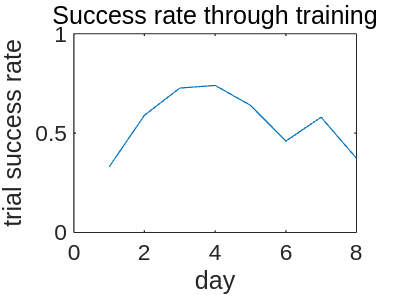

sucess_rates = [0.33, 0.59, 0.7267, 0.74, 0.64, 0.46, 0.58, 0.3733];
plot(sucess_rates);
title('Success rate through training');
xlabel('day');
ylabel('trial success rate');
ylim([0 1]);

% y = cat(1, zeros(50), ones(50));
% y = (1:100)/100;
y = log(1:100)

y =          0    0.6931    1.0986    1.3863    1.6094    1.7918    1.9459    2.0794    2.1972    2.3026    2.3979    2.4849    2.5649    2.6391    2.7081    2.7726    2.8332    2.8904    2.9444    2.9957    3.0445    3.0910    3.1355    3.1781    3.2189    3.2581    3.2958    3.3322    3.3673    3.4012    3.4340    3.4657    3.4965    3.5264    3.5553    3.5835    3.6109    3.6376    3.6636    3.6889    3.7136    3.7377    3.7612    3.7842    3.8067    3.8286    3.8501    3.8712    3.8918    3.9120


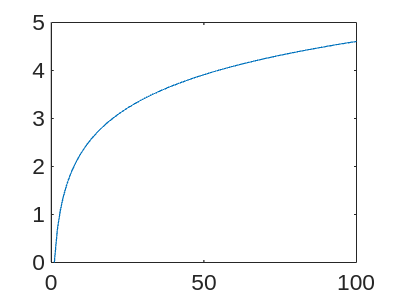

plot(y)

% ylim([-0.5 1.5]);

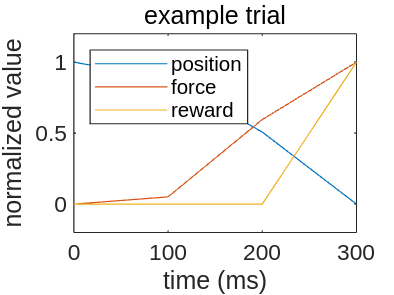

% plot example trial
i = 22;
p_time_temp_transformed = behavior_sequence_fps{i}(:,6);
p_resistance_list = behavior_sequence_fps{i}(:,2);
p_position_temp = behavior_sequence_fps{i}(:,3);
p_force_temp = behavior_sequence_fps{i}(:,4);
p_reward_temp = behavior_sequence_fps{i}(:,5);

% p_time_temp_transformed = (p_time_temp_transformed-min(p_time_temp_transformed))/(max(p_time_temp_transformed)-min(p_time_temp_transformed));
% p_resistance_list = (p_resistance_list-min(p_resistance_list))/(max(p_resistance_list)-min(p_resistance_list));
p_position_temp = (p_position_temp-min(p_position_temp))/(max(p_position_temp)-min(p_position_temp));
p_force_temp = (p_force_temp-min(p_force_temp))/(max(p_force_temp)-min(p_force_temp));
p_reward_temp = (p_reward_temp-min(p_reward_temp))/(max(p_reward_temp)-min(p_reward_temp));

% plot(p_time_temp_transformed, p_resistance_list, p_time_temp_transformed, p_position_temp, p_time_temp_transformed, p_force_temp, p_time_temp_transformed, p_reward_temp);
plot(p_time_temp_transformed, p_position_temp, p_time_temp_transformed, p_force_temp, p_time_temp_transformed, p_reward_temp);
title('example trial');
xlabel('time (ms)');
ylabel('normalized value');
ylim([-0.2 1.2]);
xlim([0 max(p_time_temp_transformed)]);
% legend({'resistance','position','force','reward'},'Location','northwest');
legend({'position','force','reward'},'Location','northwest');

% plot(position_temp);
% plot(force_temp);
% plot(reward_temp);
% hold off